# Quantal Release HW 

References: Chat GTP 

## EXERCISE 1:

Assume that there are **10 quanta available** in a nerve terminal, and for a given release event **each is released with a probability of 0.2.** For one such event, what is the probability that 0, 1, 2, 3, 4, 5, 6, 7, 8, 9, or 10 quanta will be released?

ANSWER:

*You can use the binomial probability mass function to calculate each of these probabilities. The formula for the probability of exactly k successes (quanta released) in n trials (available quanta) is:*

*Where:*

- *n is the number of trials (available quanta, which is 10 in this case).*

- *k is the number of successes (quanta released, ranging from 0 to 10).*

- *p is the probability of success for each trial (probability of a quanta being released, which is 0.2 in this case).*

- *(kn�) is the binomial coefficient, which calculates the number of ways to choose k successes out of n trials.*

% Define the parameters
n = 10;         % Number of trials (available quanta)
p = 0.2;        % Probability of success (quanta being released)

% Initialize an array to store the probabilities
probabilities = zeros(1, n+1);

% Calculate the probabilities for each possible outcome
for k = 0:n
    probabilities(k+1) = binopdf(k, n, p);
end

% Create a table with outcomes and probabilities
outcome = (0:n)';
T = table(outcome, probabilities');

% Display the table
disp(T);

    outcome       Var2   
    _______    __________

       0          0.10737
       1          0.26844
       2          0.30199
       3          0.20133
       4          0.08808
       5         0.026424
       6         0.005505
       7       0.00078643
       8       7.3728e-05
       9        4.096e-06
      10        1.024e-07



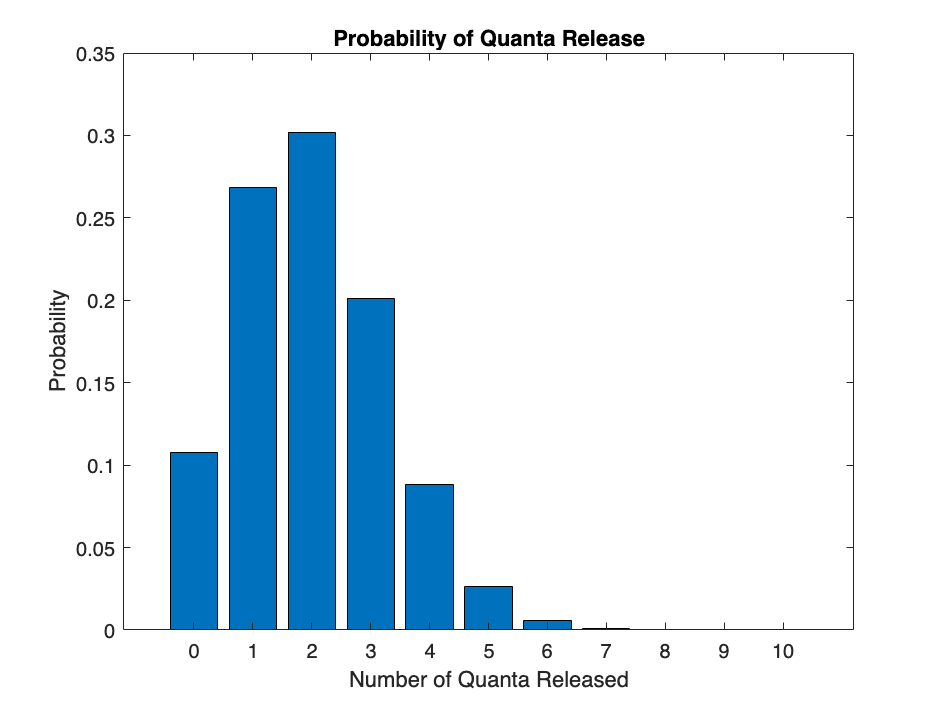


% Plot the probabilities over outcomes
bar(outcome, probabilities);
title('Probability of Quanta Release');
xlabel('Number of Quanta Released');
ylabel('Probability');

## EXERCISE 2 

Let's say you know that a given nerve terminal contains exactly 14 quanta available for release. You have read in the literature that the release probability of these quanta is low, say 0.1. To assess whether this value is reasonable, you run a simple experiment: activate the nerve and measure the number of quanta that are released. **The result is 8 quanta**. What is the probability that you would get this result (8 quanta) if the true probability of release really was 0.1? What about if the true release probability was much higher; say, 0.7? What about for each decile of release probability (0.1, 0.2, ... 1.0)? Which value of release probability did you determine to be the most probable, given your measurement?

ANSWER:

*The likelihood function for a binomial distribution describes how the conditional probability of observing a specific set of data changes ****when you hold the data fixed*** ***and vary the parameter(s) of the distribution****. In this case, you want to compute the likelihood function for the binomial distribution with known data (8 quanta released) and an unknown probability parameter (p) representing the probability of success (quanta being released).*

*The likelihood function for a single observation (in this case, 8 quanta released out of 14) in a binomial distribution is given by the binomial probability mass function:*

*Where:*

- *L(p∣x) is the likelihood function.*

- *p is the probability of success (quanta being released).*

- *x is the observed number of successes (8 quanta released).*

- *n is the total number of trials (14 quanta available for release).*

- *(xn�) is the binomial coefficient, which calculates the number of ways to choose x successes out of n trials.*

% Define the observed data
x = 8; % Observed number of successes (quanta released)
n = 14; % Total number of trials (quanta available for release)

% Define a range of possible p values (from 0 to 1)
p_values = 0:0.01:1;
likelihoods = zeros(size(p_values));

% Compute the likelihood for each p value and display them
fprintf('Probability (p)\tLikelihood\n');

Probability (p)	Likelihood


fprintf('--------------------------------\n');

--------------------------------


max_likelihood = -1; % Initialize with a small value
most_probable_p = -1;
for i = 1:length(p_values)
    p = p_values(i);
    likelihood = binopdf(x, n, p);
    likelihoods(i) = likelihood;
    
    % Display probability and likelihood
    fprintf('%0.2f\t\t\t%e\n', p, likelihood);
    
    % Check if this likelihood is the highest
    if likelihood > max_likelihood
        max_likelihood = likelihood;
        most_probable_p = p;
    end
end

0.00			0.000000e+00
0.01			2.827265e-13
0.02			6.810073e-11
0.03			1.641178e-09
0.04			1.540503e-08
0.05			8.622972e-08
0.06			3.479625e-07
0.07			1.120050e-06
0.08			3.054937e-06
0.09			7.340806e-06
0.10			1.595917e-05
0.11			3.199167e-05
0.12			5.996548e-05
0.13			1.062228e-04
0.14			1.792959e-04
0.15			2.902679e-04
0.16			4.530967e-04
0.17			6.848812e-04
0.18			1.006048e-03
0.19			1.440437e-03
0.20			2.015279e-03
0.21			2.761037e-03
0.22			3.711115e-03
0.23			4.901425e-03
0.24			6.369815e-03
0.25			8.155357e-03
0.26			1.029752e-02
0.27			1.283520e-02
0.28			1.580573e-02
0.29			1.924374e-02
0.30			2.318001e-02
0.31			2.764034e-02
0.32			3.264440e-02
0.33			3.820460e-02
0.34			4.432516e-02
0.35			5.100113e-02
0.36			5.821772e-02
0.37			6.594964e-02
0.38			7.416077e-02
0.39			8.280398e-02
0.40			9.182116e-02
0.41			1.011436e-01
0.42			1.106924e-01
0.43			1.203794e-01
0.44			1.301083e-01
0.45			1.397757e-01
0.46			1.492728e-01
0.47			1.584869e-01
0.48			1.673036e-01
0.49			1.756083e-01



% Display the most probable release probability
fprintf('\nThe release probability determined to be the most probable is %0.2f\n', most_probable_p);


The release probability determined to be the most probable is 0.57


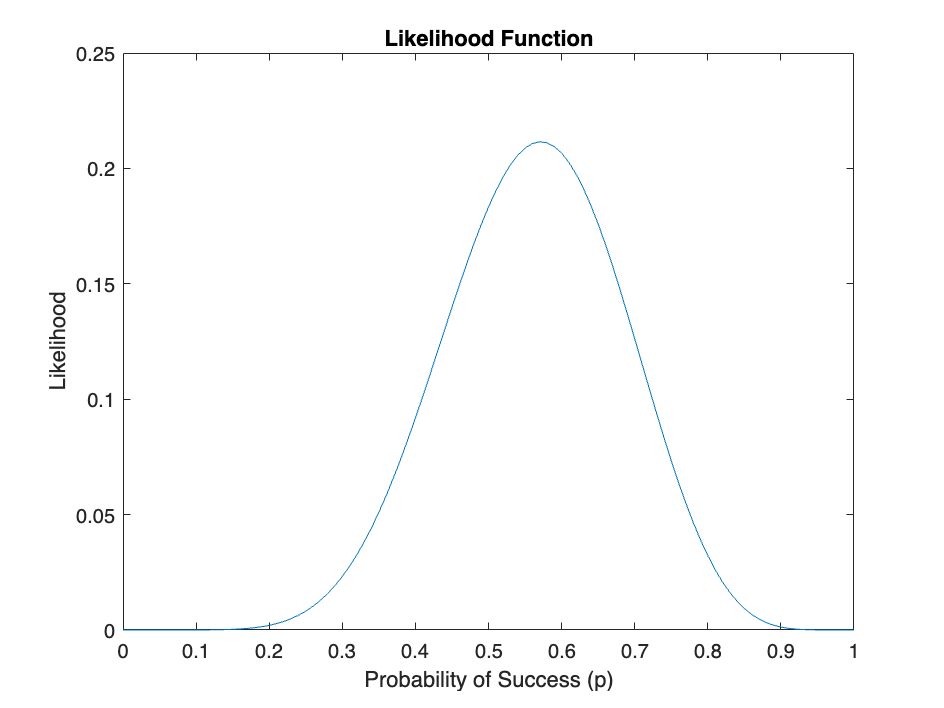


% Plot the likelihood function
figure;
plot(p_values, likelihoods);
title('Likelihood Function');
xlabel('Probability of Success (p)');
ylabel('Likelihood');

## EXERCISE 3

Not feeling convinced by your single experiment (good scientist!), you repeat it under identical conditions. This time **you measure 5 quanta that were released**. Your sample size has now doubled, to two measurements. You now want to take into account both measurements when you assess the likelihoods of different possible values of the underlying release probability. To do so, assume that the two measurements in this sample are independent of one another; that is, the value of each result had no bearing on the other. In this case, the total likelihood is simply the product of the likelihoods associated with each separate measurement. It is also typical to compute the logarithm of each likelihood and take their sum, which is often more convenient. What are the values of the total likelihood and total log-likelihood in this example, if we assume that the true release probability is 0.1?

*ANSWER:*

*it's common to compute the logarithm of each likelihood and then sum the logarithms, which is equivalent to taking the logarithm of the product. This is often done for numerical stability and simplifies calculations.*

*In your case, you want to assess the likelihood for a true release probability of 0.1, given two measurements: the first measurement is 8 quanta released out of 14, and the second measurement is 5 quanta released out of 14. Let's calculate the total likelihood and total log-likelihood for a true release probability of 0.1:*

*1.First Measurement:*

- *x1� (number of quanta released in the first measurement) = 8*

- *n1� (total number of trials in the first measurement) = 14*

*2. Second Measurement:*

- *x2� (number of quanta released in the second measurement) = 5*

- *n2� (total number of trials in the second measurement) = 14*

% Define the observed data for each measurement
x1 = 8; % First measurement: Observed number of successes (quanta released)
n1 = 14; % First measurement: Total number of trials (quanta available for release)

x2 = 5; % Second measurement: Observed number of successes (quanta released)
n2 = 14; % Second measurement: Total number of trials (quanta available for release)

% Define the true release probability
p_true = 0.1;

% Calculate the likelihood for each measurement
likelihood1 = binopdf(x1, n1, p_true);
likelihood2 = binopdf(x2, n2, p_true);

% Calculate the total likelihood by taking the product of the individual likelihoods
total_likelihood = likelihood1 * likelihood2;

% Calculate the total log-likelihood by summing the logarithms of the individual likelihoods
total_log_likelihood = log(likelihood1) + log(likelihood2);

% Display the results
fprintf('Total Likelihood: %e\n', total_likelihood);

Total Likelihood: 1.237819e-07


fprintf('Total Log-Likelihood: %f\n', total_log_likelihood);

Total Log-Likelihood: -15.904745


Of course, knowing those values of the likelihood and log-likelihood is not particularly useful until you can compare them to the values computed for other possible values for the release probability, so you can determine which value of release probability is most likely, given the data. Therefore, compute the full likelihood and log-likelihood functions using deciles of release probability between 0 and 1. What is the maximum value? Can you improve your estimate by computing the functions at a higher resolution? How does the estimate improve as you increase the sample size?

ANSWER:

*By examining the likelihood functions, you can identify the release probability that maximizes the likelihood, which is the maximum likelihood estimate (MLE).*

*Let's calculate the likelihood and log-likelihood functions for deciles of release probability values between 0 and 1 and find the maximum likelihood estimate. We'll start with a lower resolution and then increase it to see how the estimate improves as we increase the sample size*.

% Define the observed data for each measurement
x1 = 8; % First measurement: Observed number of successes (quanta released)
n1 = 14; % First measurement: Total number of trials (quanta available for release)

x2 = 5; % Second measurement: Observed number of successes (quanta released)
n2 = 14; % Second measurement: Total number of trials (quanta available for release)

% Define a range of possible release probability values (deciles)
p_values = 0:0.1:1;

% Initialize arrays to store likelihood and log-likelihood values
likelihoods = zeros(size(p_values));
log_likelihoods = zeros(size(p_values));

% Calculate the likelihood and log-likelihood for each release probability value
for i = 1:length(p_values)
    p = p_values(i);
    
    % Calculate likelihoods for each measurement
    likelihood1 = binopdf(x1, n1, p);
    likelihood2 = binopdf(x2, n2, p);
    
    % Calculate the total likelihood and log-likelihood
    total_likelihood = likelihood1 * likelihood2;
    total_log_likelihood = log(likelihood1) + log(likelihood2);
    
    % Store the results
    likelihoods(i) = total_likelihood;
    log_likelihoods(i) = total_log_likelihood;
end

% Find the release probability that maximizes the likelihood
[max_likelihood, idx_max_likelihood] = max(likelihoods);
most_probable_p_likelihood = p_values(idx_max_likelihood);

% Find the release probability that maximizes the log-likelihood
[max_log_likelihood, idx_max_log_likelihood] = max(log_likelihoods);
most_probable_p_log_likelihood = p_values(idx_max_log_likelihood);

% Display the results
fprintf('Maximum Likelihood Estimate (MLE):\n');

Maximum Likelihood Estimate (MLE):


fprintf('Release Probability: %0.2f\n', most_probable_p_likelihood);

Release Probability: 0.50


fprintf('Maximum Likelihood Value: %e\n', max_likelihood);

Maximum Likelihood Value: 2.239647e-02



fprintf('\nMaximum Log-Likelihood Estimate (MLE):\n');


Maximum Log-Likelihood Estimate (MLE):


fprintf('Release Probability: %0.2f\n', most_probable_p_log_likelihood);

Release Probability: 0.50


fprintf('Maximum Log-Likelihood Value: %f\n', max_log_likelihood);

Maximum Log-Likelihood Value: -3.798852


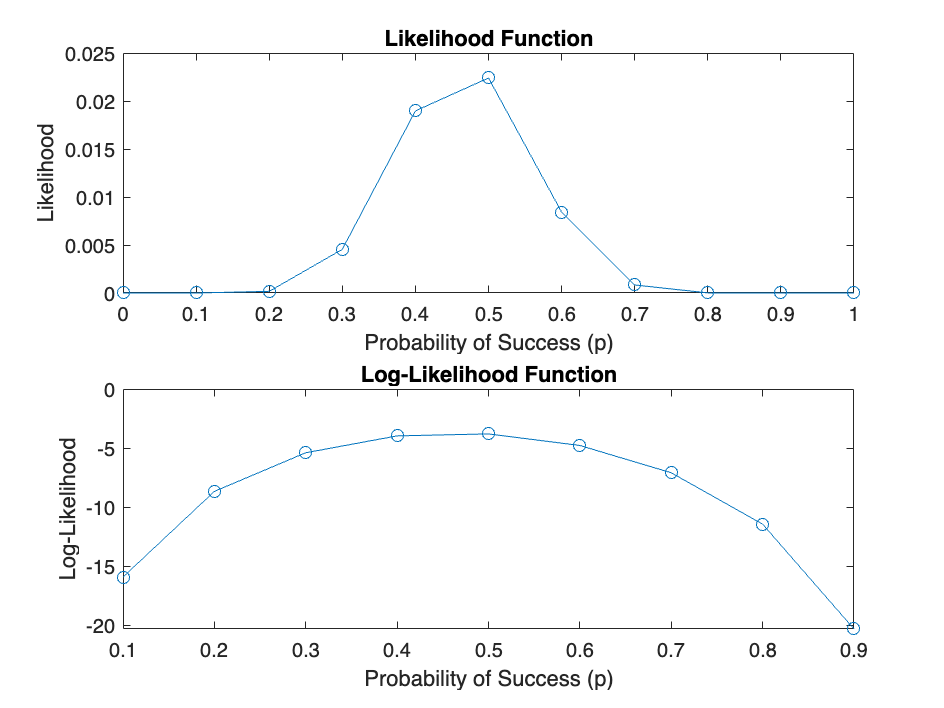


% Plot the likelihood and log-likelihood functions
figure;
subplot(2, 1, 1);
plot(p_values, likelihoods, '-o');
title('Total Likelihood Function');
xlabel('Probability of Success (p)');
ylabel('Likelihood');

subplot(2, 1, 2);
plot(p_values, log_likelihoods, '-o');
title('Total Log-Likelihood Function');
xlabel('Probability of Success (p)');
ylabel('Log-Likelihood');

**Increasing Resolution: **When you compute the likelihood and log-likelihood functions at a higher resolution (using more values of *p*), you get a more detailed view of how these functions behave. This can help you pinpoint the exact value of *p* that maximizes the likelihood or log-likelihood more accurately. The estimate becomes less sensitive to the choice of resolution, and you can identify the peak of the function more precisely. To improve the estimate by increasing resolution, you can simply reduce the spacing between the *p* values you consider within the range (e.g., use smaller increments than 0.1). This allows you to zoom in on the most likely value more effectively.

**Increasing Sample Size: **Increasing the sample size (i.e., collecting more data) generally leads to more accurate estimates of the underlying parameters, such as the release probability (*p*). As the sample size increases, the estimates tend to become less influenced by random fluctuations or noise in the data. With a larger sample size, the likelihood functions become more peaked and narrow around the true parameter value. This means that you can achieve a more precise estimate because you have more information to work with. The likelihood functions also become less sensitive to variations in the data.

## EXERCISE 4

You keep going and conduct 100 separate experiments and end up with these results:

**Measured releases Count**

0                                0

1                                0

2                                3

4                              10

5                              19

6                              26

7                              16

8                              16

9                               5

10                             5

11                             0

12                             0

13                             0

14                             0

What is the most likely value of *p* (which we typically refer to as P^, which is pronounced as "p-hat" and represents the maximum-likelihood estimate of a parameter in the population given our sample with a resolution of 0.01?

ANSWER:

*To find the maximum-likelihood estimate (p^�) of the release probability (p) given the results of 100 separate experiments, you can use the likelihood function. In this case, you have a range of measured releases (0 to 10) with corresponding counts. You'll calculate the likelihood for each value of p within a resolution of 0.01 and determine the value of p that maximizes the likelihood.*

% Define the observed data
measured_releases = [0, 1, 2, 4, 5, 6, 7, 8, 9, 10];
counts = [0, 0, 3, 10, 19, 26, 16, 16, 5, 5];

% Define a range of possible release probability values (resolution of 0.01)
p_values = 0:0.01:1;
likelihoods = zeros(size(p_values));

% Calculate the likelihood for each release probability value
for i = 1:length(p_values)
    p = p_values(i);
    
    % Calculate the likelihood for the observed data
    likelihood = prod(binopdf(measured_releases, 10, p).^counts);
    
    % Store the likelihood
    likelihoods(i) = likelihood;
end

% Find the release probability that maximizes the likelihood
[max_likelihood, idx_max_likelihood] = max(likelihoods);
p_hat = p_values(idx_max_likelihood);

% Display the results
fprintf('Maximum Likelihood Estimate (p-hat): %0.2f\n', p_hat);

Maximum Likelihood Estimate (p-hat): 0.63


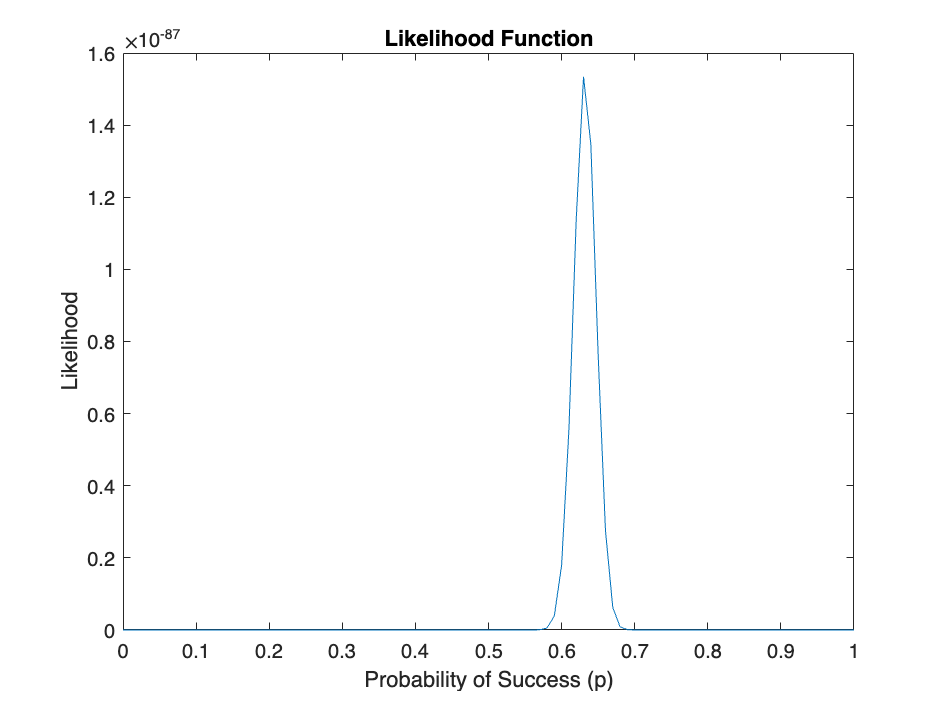


% Plot the likelihood function
figure;
plot(p_values, likelihoods);
title('Likelihood Function');
xlabel('Probability of Success (p)');
ylabel('Likelihood');

BONUS: Use a fitting procedure to find p-hat

% Define a function for the likelihood
likelihood_fun = @(p) prod(binopdf(measured_releases, 10, p).^counts);

% Find the maximum likelihood estimate using the fminsearch function
initial_guess = 0.5; % Initial guess for p
p_hat_fitting = fminsearch(@(p) -log(likelihood_fun(p)), initial_guess);

% Display the result
fprintf('Maximum Likelihood Estimate (p-hat) using fitting: %0.2f\n', p_hat_fitting);

Maximum Likelihood Estimate (p-hat) using fitting: 0.63


EXERCISE 5

Let's say that you have run an exhaustive set of experiments on this synapse and** have determined that the true release probability is 0.3 **(within some very small tolerance). Now you want to test whether changing the temperature of the preparation affects the release probability. So you change the temperature, perform the experiment, and measure 7 quantal events for the same 14 available quanta. Compute P-HAT

% Define the observed data for the new experiment
x_new = 7; % Observed number of successes (quanta released)
n_new = 14; % Total number of trials (quanta available for release)

% Define a range of possible release probability values (resolution of 0.01)
p_values = 0:0.01:1;
likelihoods = zeros(size(p_values));

% Calculate the likelihood for each release probability value
for i = 1:length(p_values)
    p = p_values(i);
    
    % Calculate the likelihood for the observed data
    likelihood = binopdf(x_new, n_new, p);
    
    % Store the likelihood
    likelihoods(i) = likelihood;
end

% Find the release probability that maximizes the likelihood
[max_likelihood, idx_max_likelihood] = max(likelihoods);
p_hat_new = p_values(idx_max_likelihood);

% Display the result
fprintf('Maximum Likelihood Estimate (p-hat) for the new experiment: %0.2f\n', p_hat_new);

Maximum Likelihood Estimate (p-hat) for the new experiment: 0.50


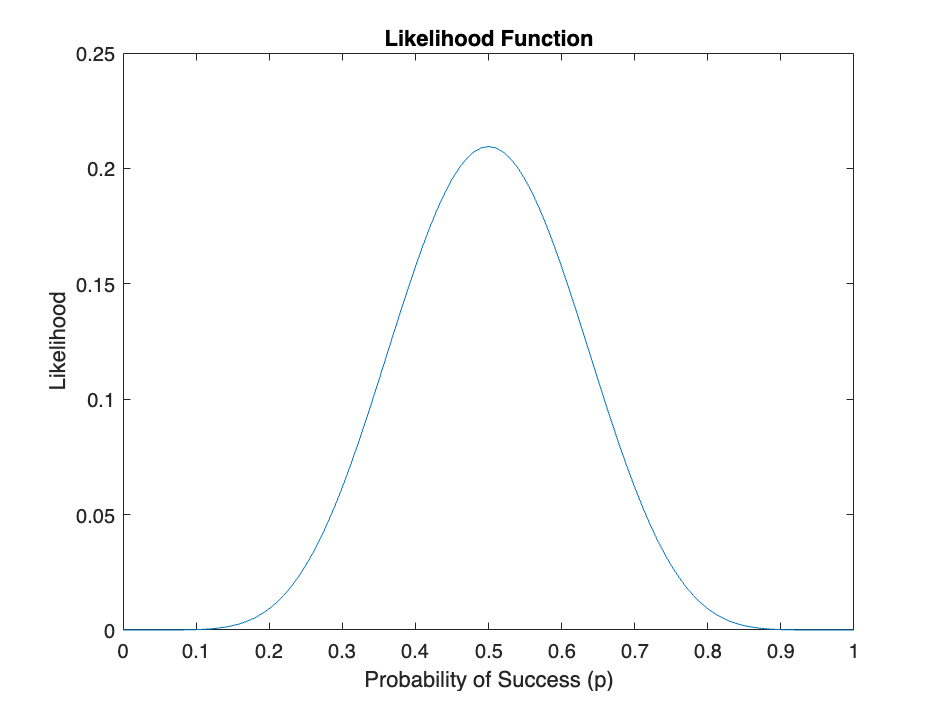


% Plot the likelihood function
figure;
plot(p_values, likelihoods);
title('Likelihood Function');
xlabel('Probability of Success (p)');
ylabel('Likelihood');

Standard statistical inference now asks the question, what is the probability that you would have obtained that measurement given a Null Hypothesis of no effect? In this case, no effect corresponds to an unchanged value of the true release probability (i.e., its value remained at 0.3 even with the temperature change). What is the probability that you would have gotten that measurement if your Null Hypothesis were true? Can you conclude that temperature had an effect?

ANSWER:

To assess whether the change in temperature had an effect on the release probability, you can perform a hypothesis test. In this case, the null hypothesis (*H*0�) is that there is no effect of temperature change, meaning that the true release probability (*p*) remains at 0.3, while the alternative hypothesis (*H*1�) is that the true release probability (*p*) has changed due to the temperature effect.

To perform the hypothesis test, you can calculate the probability of observing a measurement as extreme as the one you obtained (7 quantal events out of 14 trials) under the assumption that the null hypothesis (*H*0�) is true. This probability is called the p-value.

Here's how you can calculate the p-value:

- Calculate the probability of observing 7 or fewer quantal events out of 14 trials under the null hypothesis (*H*0�). You can use the binomial probability mass function for this calculation.

- Compare the calculated p-value to a significance level (*α*), such as 0.05. If the p-value is less than or equal to *α*, you would reject the null hypothesis (*H*0�) in favor of the alternative hypothesis (*H*1�). If the p-value is greater than *α*, you would fail to reject the null hypothesis.

% Define the observed data for the new experiment
x_new = 7; % Observed number of successes (quanta released)
n_new = 14; % Total number of trials (quanta available for release)

% Define the null hypothesis: true release probability remains at 0.3
p_null = 0.3; % Under the null hypothesis

% Calculate the probability of observing 7 or fewer quantal events under H0
p_value = sum(binopdf(0:7, n_new, p_null));

% Display the result
fprintf('Null Hypothesis (H0): True release probability remains at %0.2f\n', p_null);

Null Hypothesis (H0): True release probability remains at 0.30


fprintf('Observed Data: %d quantal events out of %d trials\n', x_new, n_new);

Observed Data: 7 quantal events out of 14 trials


fprintf('Calculated p-value: %0.4f\n', p_value);

Calculated p-value: 0.9685



% Define the significance level (alpha)
alpha = 0.05; % Adjust as needed

% Perform hypothesis test
if p_value <= alpha
    fprintf('Result: Reject the null hypothesis (H0) - Temperature had an effect on release probability.\n');
else
    fprintf('Result: Fail to reject the null hypothesis (H0) - Insufficient evidence to conclude an effect of temperature.\n');
end

Result: Fail to reject the null hypothesis (H0) - Insufficient evidence to conclude an effect of temperature.
